% Main File to generate Combined Calcium FLUX Analysis for all models
% Replicates logic from FINAL_OverlayPlot_Calcium_v2 but for Flux currents
close all; clear; clc;

% Load initial conditions and the original baseline parameters
load ICs_baseline;
load baseline_parameter_inputs;

% Store a clean copy of the baseline parameters
original_baseline_params = baseline_parameter_inputs;

% ========================================================================
%  START: BATCH SIMULATION BLOCK
% ========================================================================

num_models = 5; 
% Storage for time-course traces
all_time_flux = cell(1, num_models);
all_flux_serca = cell(1, num_models);
all_flux_ncx = cell(1, num_models);
all_flux_ipca = cell(1, num_models);

% Storage for final percentage contributions (for bar chart)
final_contrib_matrix = zeros(num_models, 3); % Columns: SERCA, NCX, PMCA

model_legends = cell(1, num_models);

% --- Loop through each model from 0 (Baseline) to 4 ---
for model_id = 0:(num_models - 1)

    fprintf('Processing Model ID: %d... ', model_id);

    % --- 1. Define Parameter Indices ---
    g_Kr_index = 2;   
    g_Na_index = 7;  
    p_CaL_index = 5; 
    g_K1_index = 1;   
    C_persist_CaL_index = 86; 
    C_persist_NaL_index = 87; 

    % --- 2. Reset parameters ---
    modified_params = original_baseline_params;
    modified_params(83) = 1; % Pacing ON

    baseline_C_persist_CaL = modified_params(C_persist_CaL_index);
    baseline_C_persist_NaL = modified_params(C_persist_NaL_index);

    % Standard Kernik-Clancy Mature adjustments
    modified_params(g_K1_index) = modified_params(g_K1_index) * 5; 
    modified_params(g_Na_index) = modified_params(g_Na_index) * 1.45; 

    % --- 3. Apply Modifications (Matching OverlayPlot_Calcium_v2) ---
    if model_id == 0
        plot_title = 'Baseline';
    elseif model_id == 1
        plot_title = 'Model 1 (IKr Defect)';
        modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
    elseif model_id == 2
        plot_title = 'Model 2 (IKr + INaL)';
        modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
        modified_params(C_persist_NaL_index) = baseline_C_persist_NaL * 2.31*3;
    elseif model_id == 3
        plot_title = 'Model 3 (IKr + ICaL)';
        modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
        modified_params(C_persist_CaL_index) = baseline_C_persist_CaL * 2.29;
    elseif model_id == 4
        plot_title = 'Model 4 (All Defects)'; 
        modified_params(g_Kr_index) = modified_params(g_Kr_index) * (1 - 0.725);
        modified_params(C_persist_NaL_index) = baseline_C_persist_NaL * 2.31*3;
        modified_params(C_persist_CaL_index) = baseline_C_persist_CaL * 2.29;
    end
    model_legends{model_id + 1} = plot_title;

    % --- 4. Run ODE Simulation ---
    options = odeset('MaxStep',1,'InitialStep',2e-2);
    run_time = 6e3; 
    [Time, values] = ode15s(@ipsc_function,[0, run_time],Y_init, options, modified_params);
    
    % --- 5. Recover Currents (Post-Processing) ---
    % ODE15s only gives us State Variables. We need Iup, INaCa, IpCa.
    % We must loop through the solution to recalculate currents.
    INaCa = zeros(size(Time));
    IpCa = zeros(size(Time));
    Iup = zeros(size(Time));
    
    for k = 1:size(values,1)
        [~, currents_step] = ipsc_function(Time(k), values(k,:), modified_params);
        % Mapping based on ipsc_function.m:
        % currents = [i_K1, i_to, i_Kr, i_Ks, i_CaL, i_NaK, i_Na, i_NaCa, i_PCa, ...
        %             i_f, i_b_Na, i_b_Ca, i_rel, i_up, i_leak, i_stim, i_CaT];
        INaCa(k) = currents_step(8);
        IpCa(k)  = currents_step(9);
        Iup(k)   = currents_step(14);
    end

    % --- 6. Flux Calculation Math (from ca_analysis_v6.m) ---
    
    % Constants needed for math
    V_tot=3960; Vc_tenT=16404; VSR_tenT=1094; V_tot_tenT=Vc_tenT+VSR_tenT;
    Vc=V_tot*(Vc_tenT/V_tot_tenT);
    Cm = 60; F = 96.4853415;

    % Isolate Beat (using 1200-2400 logic)
    inds_time_1200 = find(Time > 1200, 1, 'first');
    inds_time_2400 = find(Time > 2400, 1, 'first');
    Cai = values(:,3);
    [~, temp_ind1] = min(Cai(1:inds_time_1200));
    [~, temp_ind2] = min(Cai(inds_time_1200:inds_time_2400));
    inds1 = temp_ind1; % Should usually be start
    inds2 = inds_time_1200 + temp_ind2 - 1;

    % Calculate Flux Integrals (Cumulative)
    intJserca = cumtrapz(Time, Iup);
    intIncx_ca = cumtrapz(Time, -INaCa*2*Cm/(2.0*Vc*F));
    intIpca = cumtrapz(Time, IpCa*Cm/(2.0*Vc*F));

    % Extract just the beat flux
    fluxJserca = intJserca(inds1:inds2) - intJserca(inds1);
    fluxIncx_ca = intIncx_ca(inds1:inds2) - intIncx_ca(inds1);
    fluxIpca = intIpca(inds1:inds2) - intIpca(inds1);

    % Normalize
    flux_total = fluxJserca + fluxIncx_ca + fluxIpca;
    ref = max(flux_total);
    
    fluxJserca_norm = fluxJserca ./ ref;
    fluxIncx_ca_norm = fluxIncx_ca ./ ref;
    fluxIpca_norm = fluxIpca ./ ref;
    
    time_beat = Time(inds1:inds2);
    time_flux_norm = (time_beat - time_beat(1)); % ms, starting at 0

    % --- 7. Store Data ---
    all_time_flux{model_id+1} = time_flux_norm;
    all_flux_serca{model_id+1} = fluxJserca_norm;
    all_flux_ncx{model_id+1}   = fluxIncx_ca_norm;
    all_flux_ipca{model_id+1}  = fluxIpca_norm;
    
    % Store final percentages for bar chart
    final_contrib_matrix(model_id+1, 1) = fluxJserca_norm(end) * 100;
    final_contrib_matrix(model_id+1, 2) = fluxIncx_ca_norm(end) * 100;
    final_contrib_matrix(model_id+1, 3) = fluxIpca_norm(end) * 100;

    fprintf('Done.\n');

end

Processing Model ID: 0... 

Done.


Processing Model ID: 1... 

Done.


Processing Model ID: 2... 

Done.


Processing Model ID: 3... 

Done.


Processing Model ID: 4... 

Done.


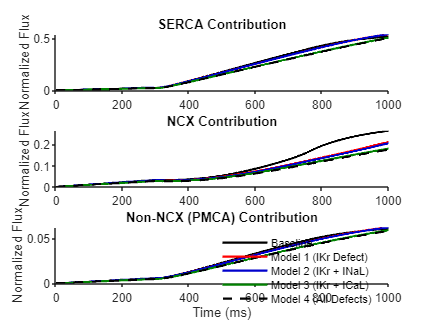


% ========================================================================
%  START: PLOTTING BLOCK
% ========================================================================

% Colors: Baseline(Blk), M1(Red), M2(Blue), M3(Green), M4(Black Dashed)
colors = [0 0 0; 1 0 0; 0 0 0.8; 0 0.5 0; 0 0 0];

%% FIGURE 1: Trace Overlays (Time Course)
figure('Name', 'Flux Trace Overlays', 'Color', 'w');

% --- Subplot 1: SERCA ---
subplot(3,1,1); hold on;
for i = 1:num_models
    line_style = '-'; if i==5, line_style = '--'; end
    plot(all_time_flux{i}, all_flux_serca{i}, 'Color', colors(i,:), 'LineStyle', line_style, 'LineWidth', 1.5);
end
title('SERCA Contribution');
ylabel('Normalized Flux');
set(gca, 'box', 'off', 'tickdir', 'out');
xlim([0 1000]); % Focus on first 1000ms usually sufficient

% --- Subplot 2: NCX ---
subplot(3,1,2); hold on;
for i = 1:num_models
    line_style = '-'; if i==5, line_style = '--'; end
    plot(all_time_flux{i}, all_flux_ncx{i}, 'Color', colors(i,:), 'LineStyle', line_style, 'LineWidth', 1.5);
end
title('NCX Contribution');
ylabel('Normalized Flux');
set(gca, 'box', 'off', 'tickdir', 'out');
xlim([0 1000]);

% --- Subplot 3: Non-NCX (PMCA) ---
subplot(3,1,3); hold on;
for i = 1:num_models
    line_style = '-'; if i==5, line_style = '--'; end
    plot(all_time_flux{i}, all_flux_ipca{i}, 'Color', colors(i,:), 'LineStyle', line_style, 'LineWidth', 1.5);
end
title('Non-NCX (PMCA) Contribution');
ylabel('Normalized Flux');
xlabel('Time (ms)');
set(gca, 'box', 'off', 'tickdir', 'out');
xlim([0 1000]);

% Legend just on bottom plot to save space, or create a dummy one
legend(model_legends, 'Location', 'southeast');
legend boxoff;

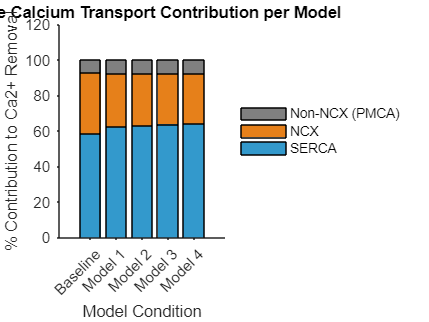


%% FIGURE 2: Bar Chart (Total % Contribution)
% Comparisons of the final values are often easier to read as bars
figure('Name', 'Flux Contribution Percentages', 'Color', 'w');

b = bar(final_contrib_matrix, 'stacked');
% Set colors for the segments (Not models, but Mechanisms)
% 1=SERCA (Light Blue), 2=NCX (Orange), 3=PMCA (Gray)
b(1).FaceColor = [0.2 0.6 0.8]; 
b(2).FaceColor = [0.9 0.5 0.1];
b(3).FaceColor = [0.5 0.5 0.5];

title('Relative Calcium Transport Contribution per Model');
ylabel('% Contribution to Ca2+ Removal');
xlabel('Model Condition');

set(gca, 'XTickLabel', {'Baseline', 'Model 1', 'Model 2', 'Model 3', 'Model 4'});
xtickangle(45);
set(gca, 'box', 'off', 'tickdir', 'out');

legend({'SERCA', 'NCX', 'Non-NCX (PMCA)'}, 'Location', 'eastoutside');
legend boxoff;


% Print Table to Command Window
fprintf('\n--- Flux Contribution Table (%%) ---\n');


--- Flux Contribution Table (%) ---


fprintf('%-20s | %-10s | %-10s | %-10s\n', 'Model', 'SERCA', 'NCX', 'PMCA');

Model                | SERCA      | NCX        | PMCA      


fprintf('-----------------------------------------------------------\n');

-----------------------------------------------------------


for i = 1:num_models
    fprintf('%-20s | %10.2f | %10.2f | %10.2f\n', ...
        model_legends{i}, ...
        final_contrib_matrix(i,1), ...
        final_contrib_matrix(i,2), ...
        final_contrib_matrix(i,3));
end

Baseline             |      58.59 |      34.06 |       7.36
Model 1 (IKr Defect) |      62.57 |      29.82 |       7.60
Model 2 (IKr + INaL) |      62.97 |      29.42 |       7.61
Model 3 (IKr + ICaL) |      63.77 |      28.68 |       7.55
Model 4 (All Defects) |      64.24 |      28.21 |       7.55
